Семинар 3.

## **Тема:** "Решение переопределенной системы линейных алгебраических уравнений"

**Задание:** Сигнал f(x) измеряется в точках c погрешностью, не превышающей $\delta$. Аппроксимировать f(x) полиномом.

clc;
clear;
N = 50

N = 50

x = -1:2/N:1;
d_x = 0.1

d_x = 0.1000

disturbance = -d_x + 2*d_x*rand(size(x));
fd_x = cos(x) + disturbance

fd_x =     0.5513    0.6651    0.5219    0.6193    0.6538    0.6830    0.7480    0.7462    0.7293    0.7938    0.7877    0.8602    0.9312    0.9687    0.9344    1.0102    0.8661    0.9551    0.8977    0.8936    0.8844    1.0302    1.0392    0.9296    1.0126    1.0654    1.0651    0.9644    1.0865    1.0669    0.9072    0.9074    0.9003    0.9329    0.9620    0.9957    0.8543    0.8166    0.7737    0.7792    0.7779    0.8306    0.6779    0.7606    0.7001    0.6031    0.7407    0.7247    0.6158    0.5040


M = 4

M = 4

system = [];
for i = 0:M
  column = (x.^i)';
  system = horzcat(system, column);
end;
p = system\fd_x'

p =     1.0037
   -0.0393
   -0.6016
    0.0459
    0.1572


cond(system)

ans = 18.0573

norm(cos(x)' - system * p)

ans = 0.1074

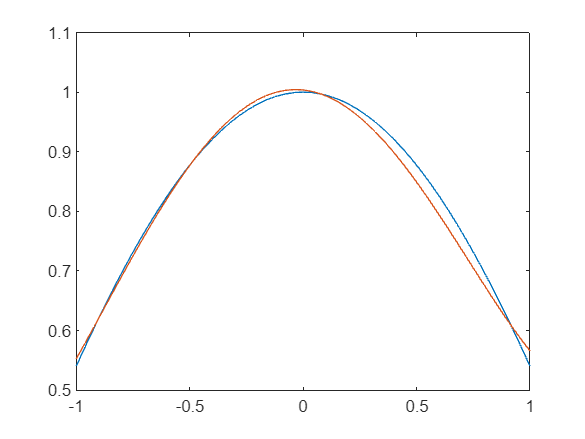


plot(x, cos(x))
hold on;
plot(x, system * p)
hold off;